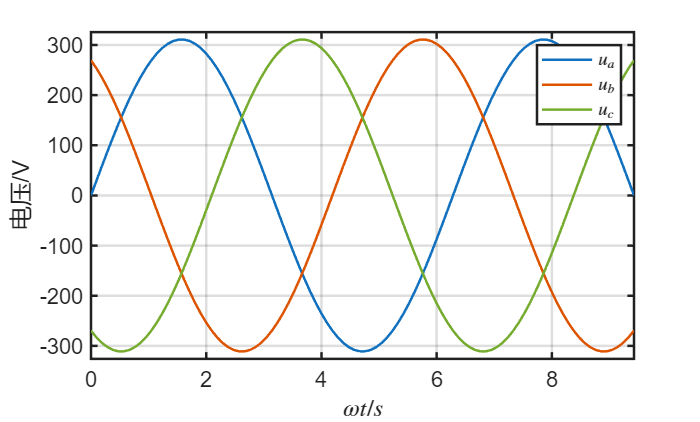

clc,clear,close all
tic
format long g
Ul=380;
Um=220;
f=50;
%w=2*pi*f;
w=1;
t=linspace(0,3*pi/w);
ua=Um*sqrt(2)*sin(w*t);
ub=Um*sqrt(2)*sin(w*t+2*pi/3);
uc=Um*sqrt(2)*sin(w*t-2*pi/3);
plot(t,ua,t,ub,"LineWidth",1.5)
hold on
plot(t,uc,"LineWidth",1.5,...
    "Color",[0.46 0.67 0.18])
xlim([min(t),max(t)])
ylim([min(ua)-15,max(ua)+15])
h=legend('$u_a$','$u_b$','$u_c$');
set(h,'Interpreter','latex')
grid on;
set(gca,'LineWidth',1.5,'FontSize',13);
xlabel('$\omega t/s$',"Interpreter","latex")
ylabel('电压/V')

toc

历时 2.907226 秒。
